# `Lista 4`

`Hubert Jackowski`

## `Układ RLC`

`RLC – skrótowe oznaczenie dla obwodów elektrycznych (w tym elektronicznych) składających się tylko z trzech podstawowych elementów pasywnych:rezystora, oznaczanego przez R (rezystancja),cewki, oznaczanej przez L (indukcyjność),kondensatorów, oznaczanych przez C (pojemność).`

#### `MODEL`

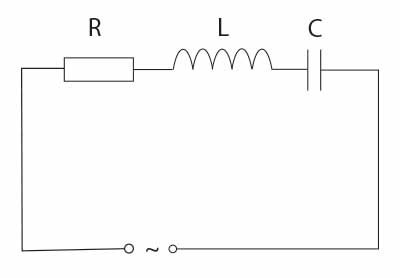

`Figure 1: Fizyczny i matematyczny model układu RLC`

def RLC(q0: float, i0: float, R: float, L: float, C: float, A: float, Omega: float):
    t = sp.symbols('t')
    q = sp.Function('q')(t)
    i = sp.Function('i')(t)

    eq1 = sp.Eq(q.diff(t), i)
    eq2 = sp.Eq(L * i.diff(t) + R * i + q / C, A * sp.cos(Omega * t))

    solution = sp.dsolve((eq1, eq2), ics={q.subs(t, 0): q0, i.subs(t, 0): i0})

    return solution

def simulate(q0: float, i0: float, R: float, L: float, C: float, A: float, Omega: float, dt: float, time: float):
    equations: list[sp.Eq] = DynamicModel.SympySolver.RLC(q0, i0, R, C, L, A, Omega)
    numberOfSteps = int(time / dt)
    systemEvolution = []
    for equation in equations:
        eqEvolution = []
        for step in range(numberOfSteps):
            eqEvolution.append(equation.rhs.subs("t", dt * step))
        systemEvolution.append(eqEvolution)
    return systemEvolution

`Figure 2: Realizacja modelu układu RLC za pomocą biblioteki sympy w języku Python`

def simulate(q0: float, i0: float, R: float, L: float, C: float, A: float, Omega: float, dt: float,
             time: float):
    def _V(_t, a: float, omega: float):
        return a * np.cos(omega * _t)

    def _RLC(y, _t, _R, _L, _C):
        q, i = y

        dqdt = i
        didt = (1 / _L) * (_V(_t, A, Omega) - _R * i - q / _C)

        return [dqdt, didt]

    y0 = [q0, i0]
    t = np.arange(0.0, time, dt)
    solution = odeint(_RLC, y0, t, args=(R, L, C))
    return solution.T

`Figure 3: Realizacja modelu układu RLC za pomocą metody scipy.integrate.odeint w języku Python`

`ŚREDNI BŁĄD APROKSYMACJI`

`Figure 4: Matematyczny wzór średniego błędu bezwzględnego`

`Figure 5: Matematyczny wzór średniego błędu kwadratowego`

#### `OBSERWACJE`

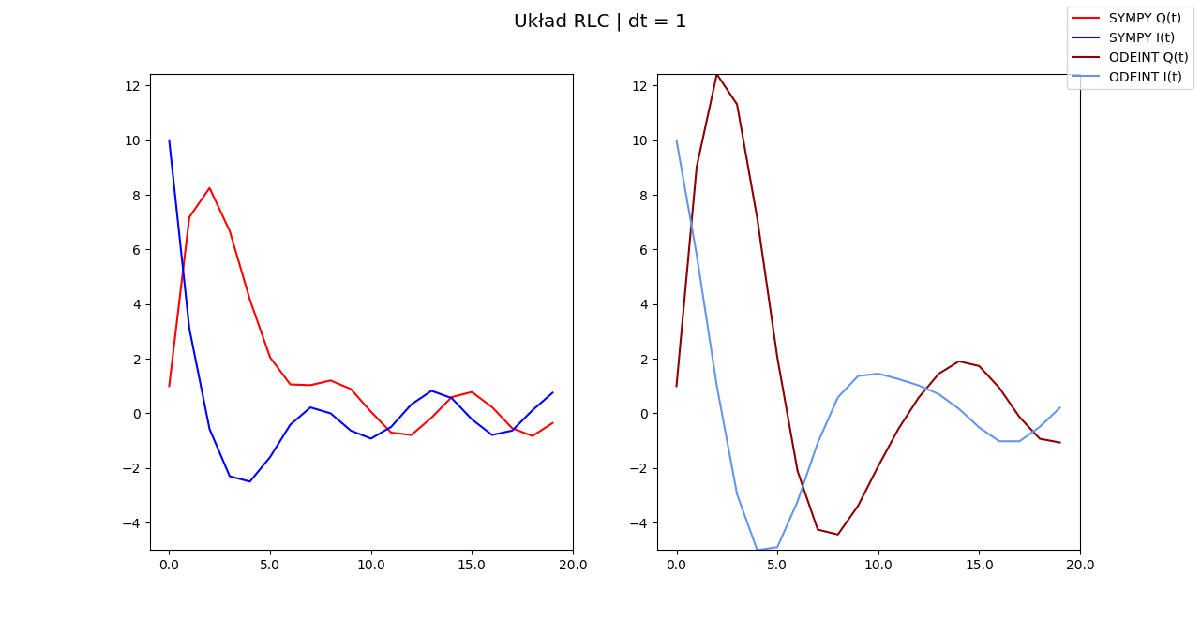

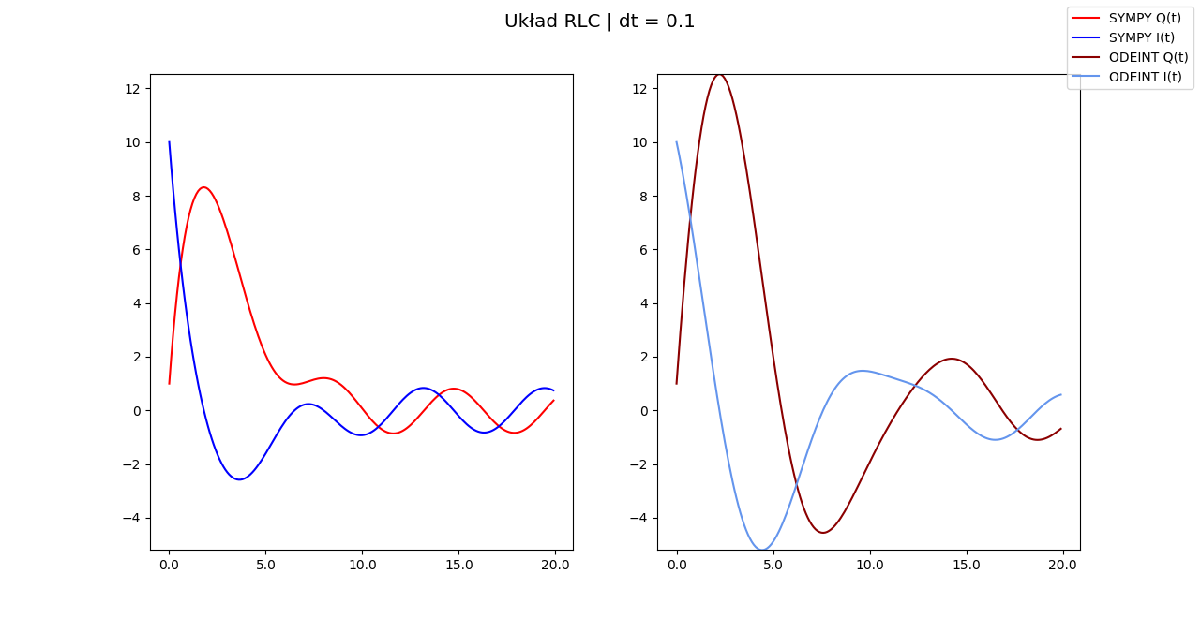

`Figure 6: Wykresy I(t), Q(t) układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 1`

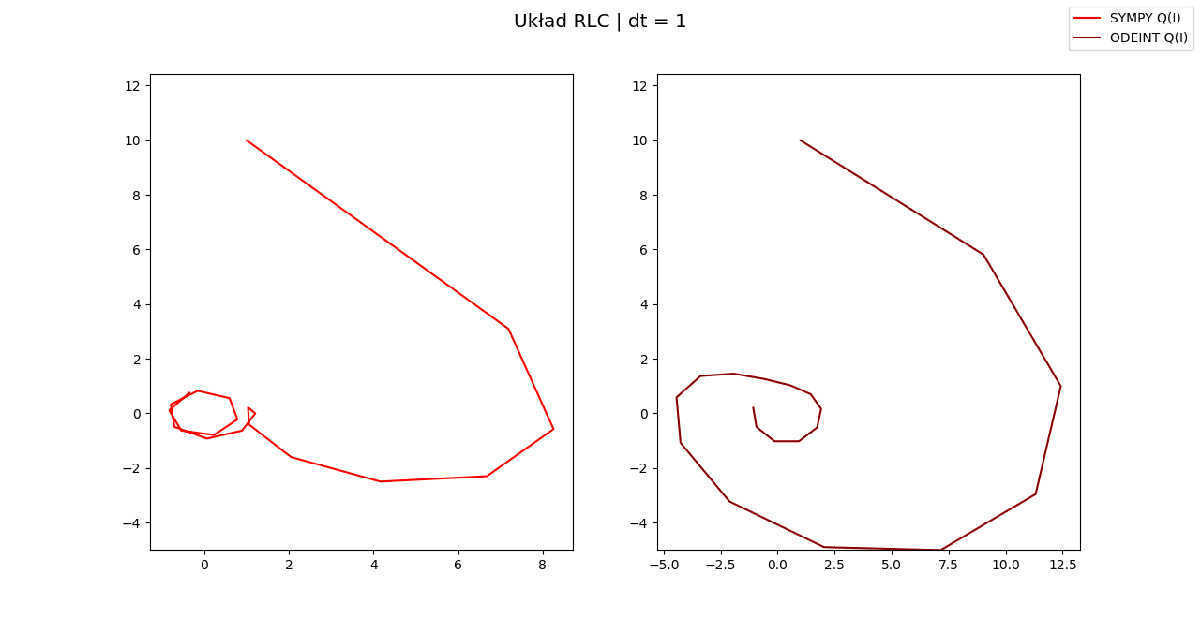

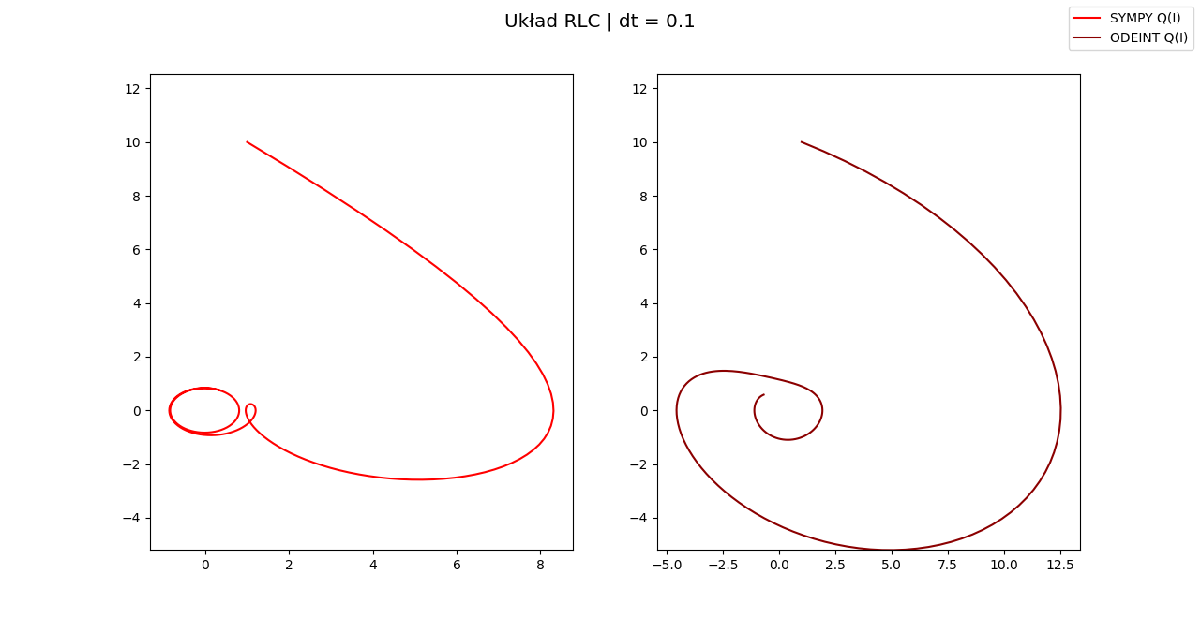

`Figure 7: Wykresy Q(I) układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 1`

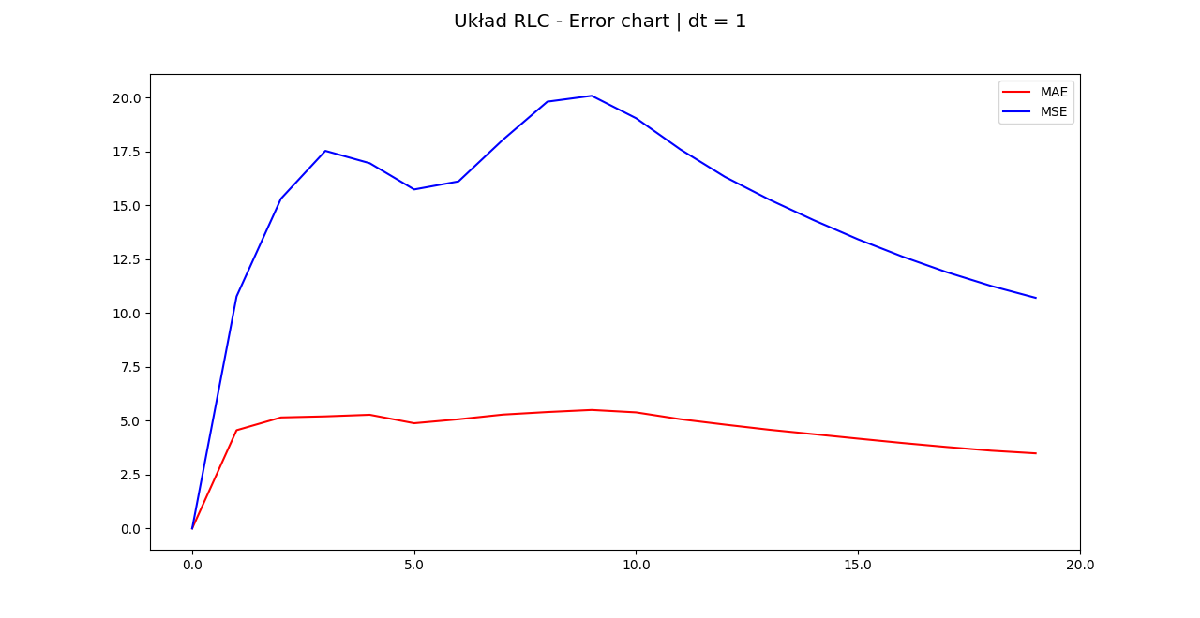

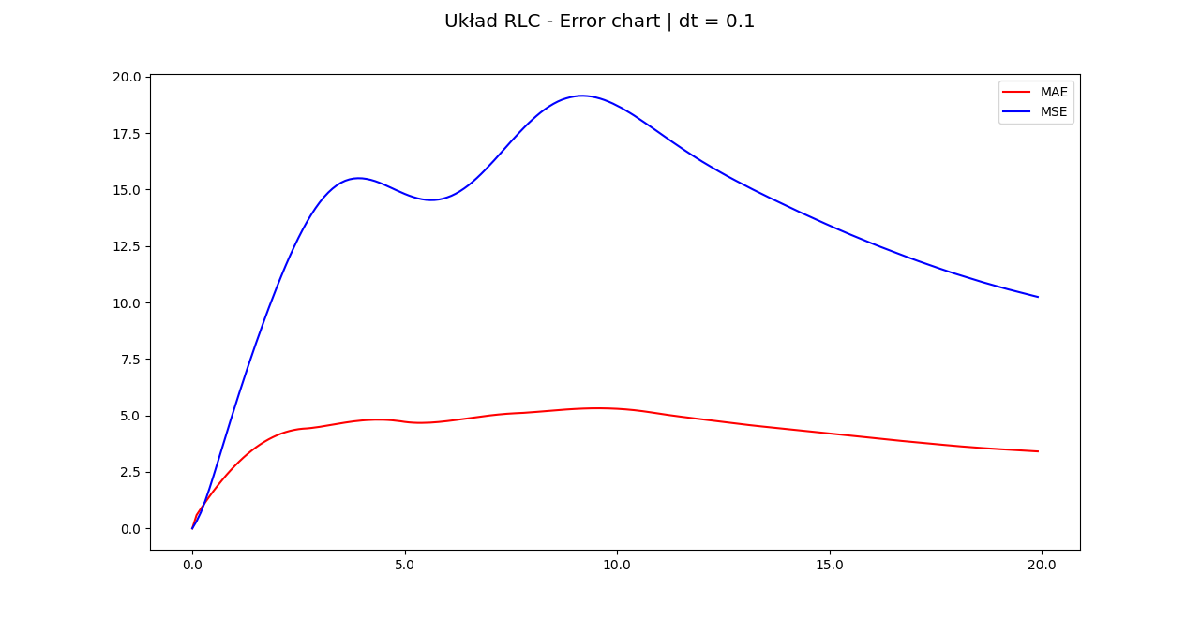

`Figure 8: Wykresy średniego błędu kwadratowego i średniego błędu bezwzględnego układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 1`

`ŚREDNI BŁĄD APROKSYMACJI`

- `dt = 1`

MSE:  10.165,  MAE:  3.3094

- `dt = 0.1`

 MSE:  10.208,  MAE:  3.3887

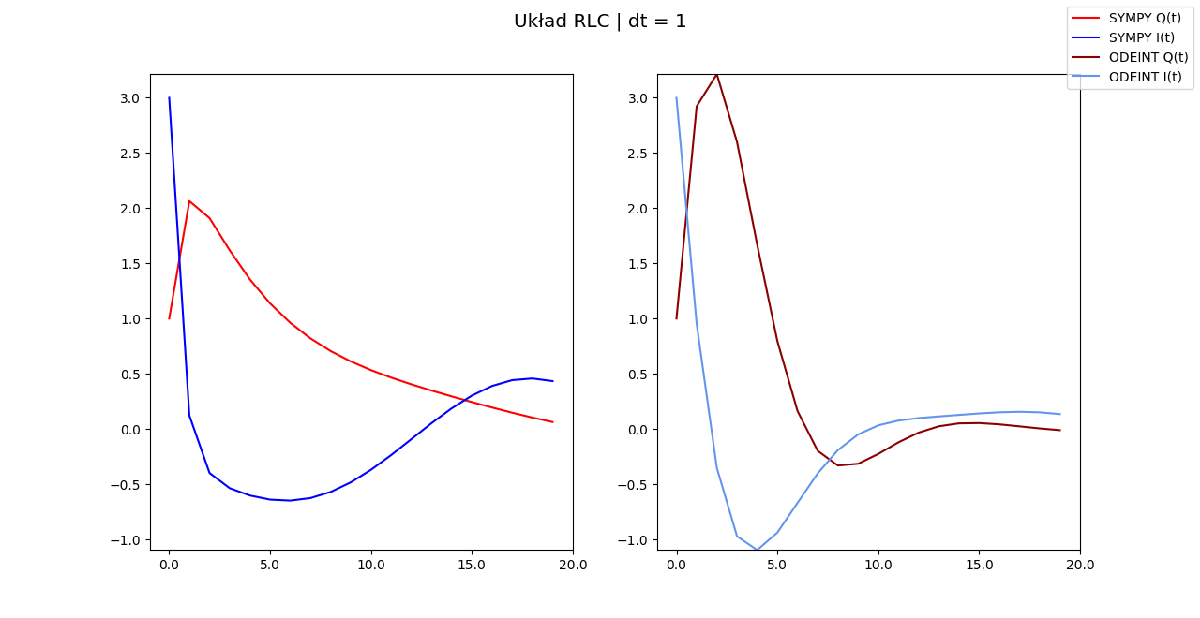

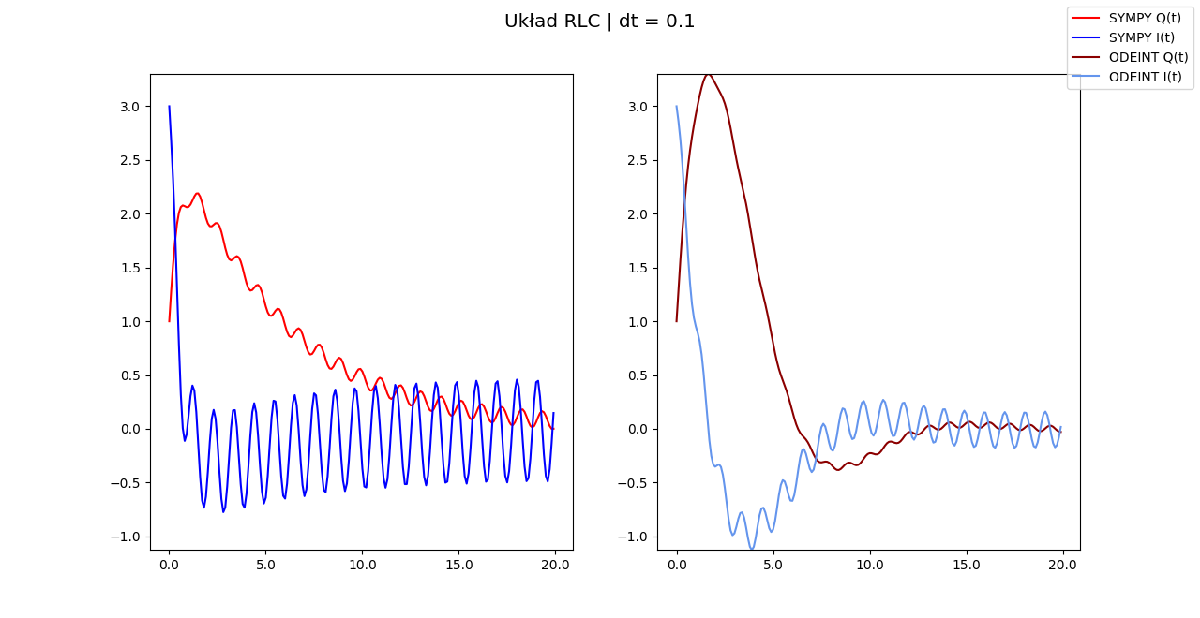

`Figure 9: Wykresy I(t), Q(t) układu RLC przy parametrach q0 = 1, i0 = 3, R = 2, L = 3, C = 1, A = 3, Omega = 6`

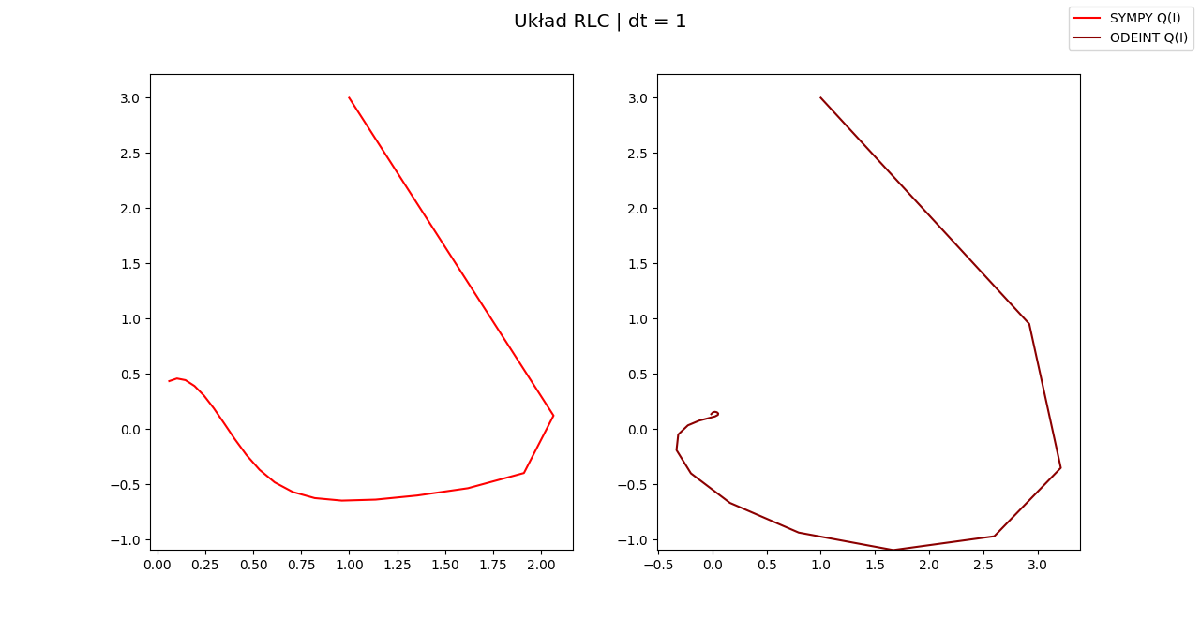

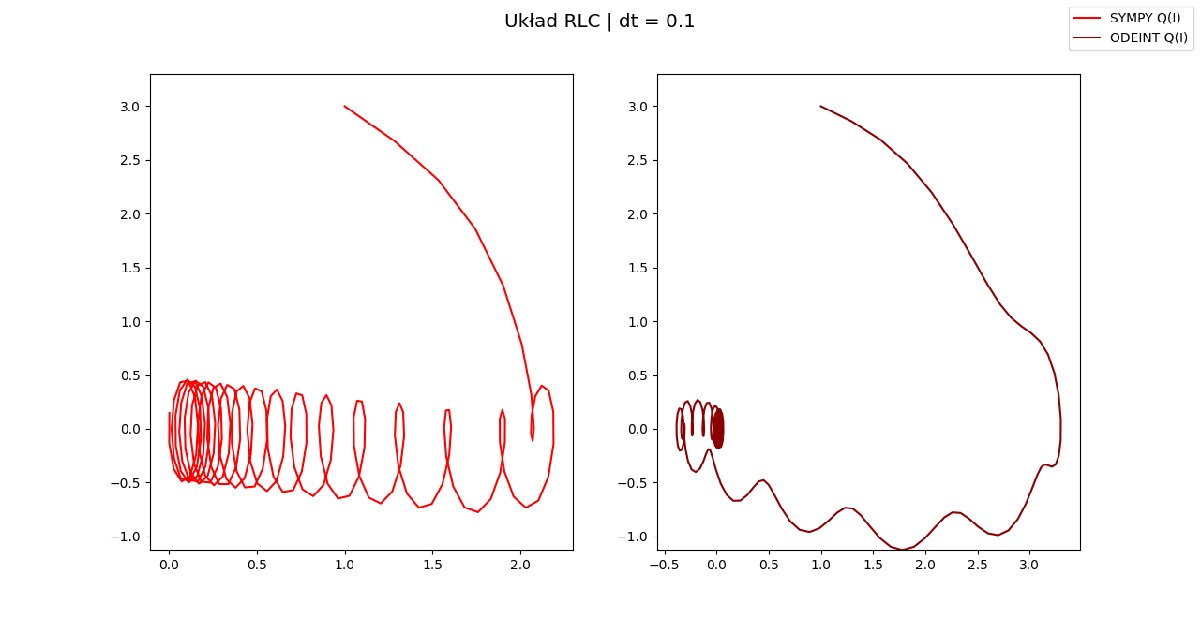

`Figure 10: Wykresy Q(I) układu RLC przy parametrach q0 = 1, i0 = 3, R = 2, L = 3, C = 1, A = 3, Omega = 6`

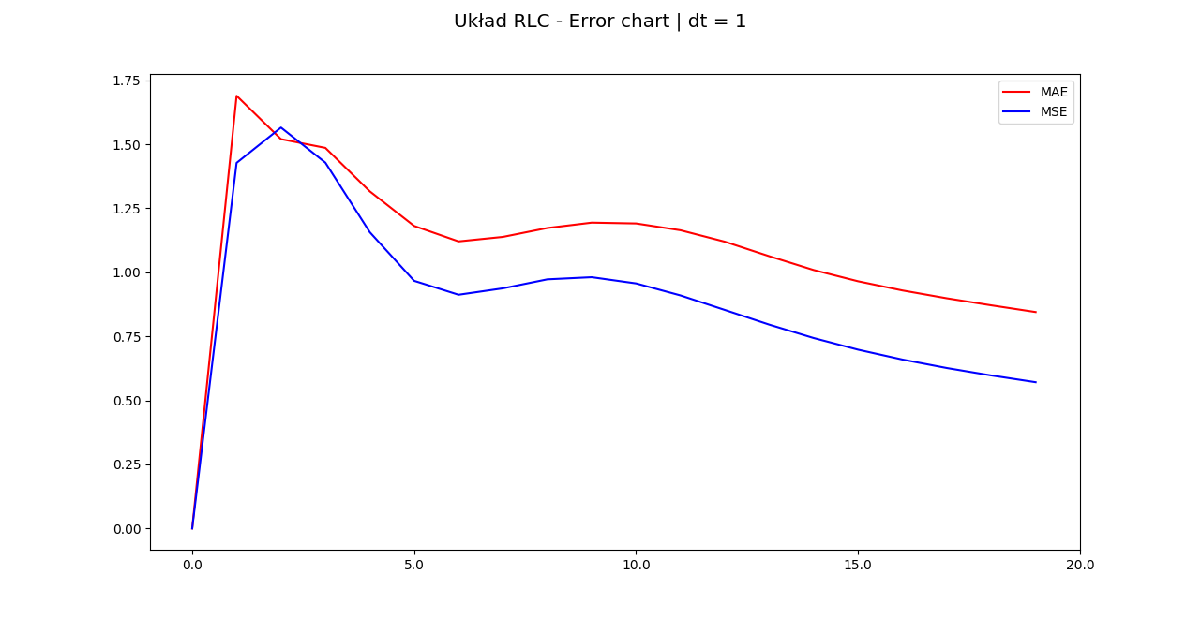

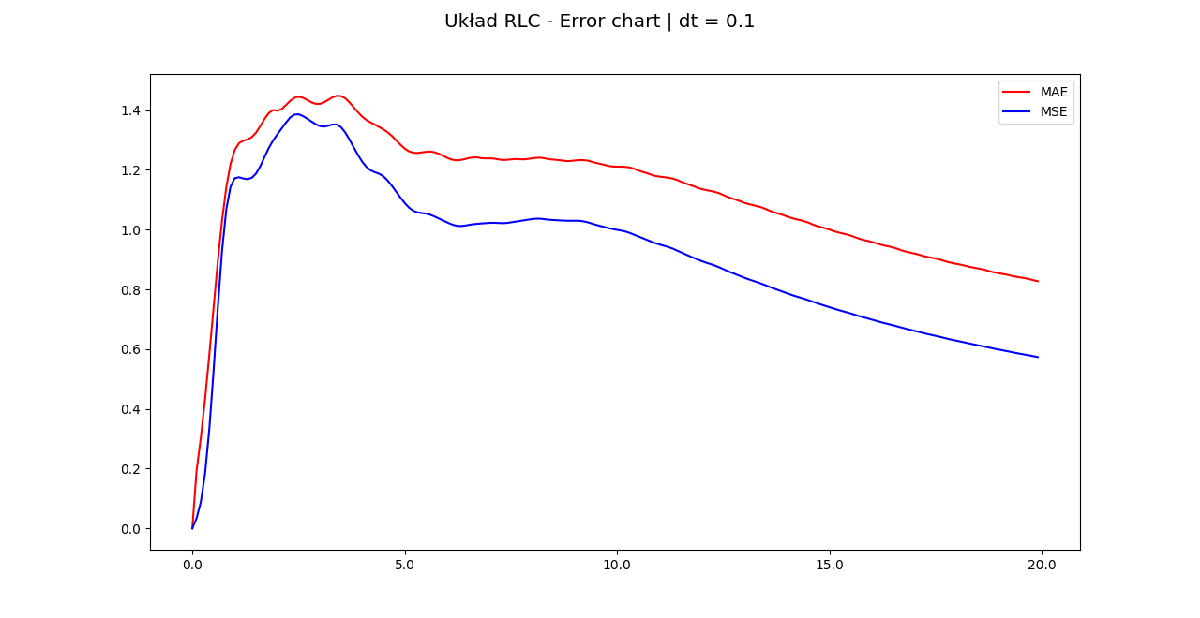

`Figure 11: Wykresy średniego błędu kwadratowego i średniego błędu bezwzględnego układu RLC przy parametrach q0 = 1, i0 = 3, R = 2, L = 3, C = 1, A = 3, Omega = 6`

`ŚREDNI BŁĄD APROKSYMACJI`

- `dt = 1`

MSE:  0.54235,  MAE:  0.80282

- `dt = 0.1`

MSE:  0.57044,  MAE:  0.82354

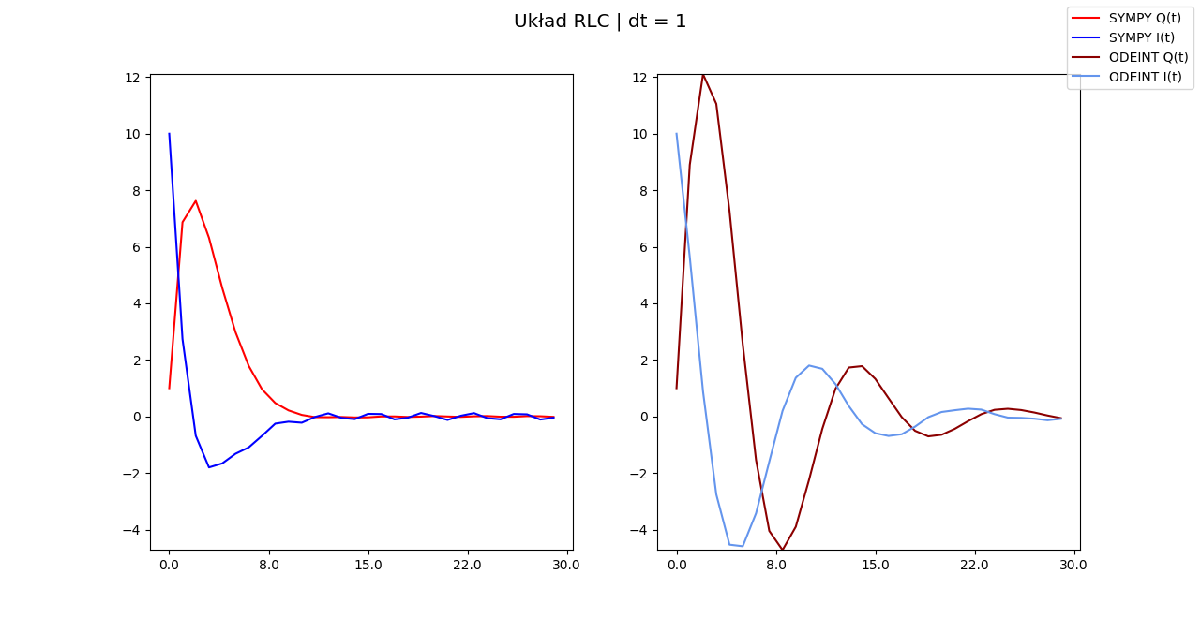

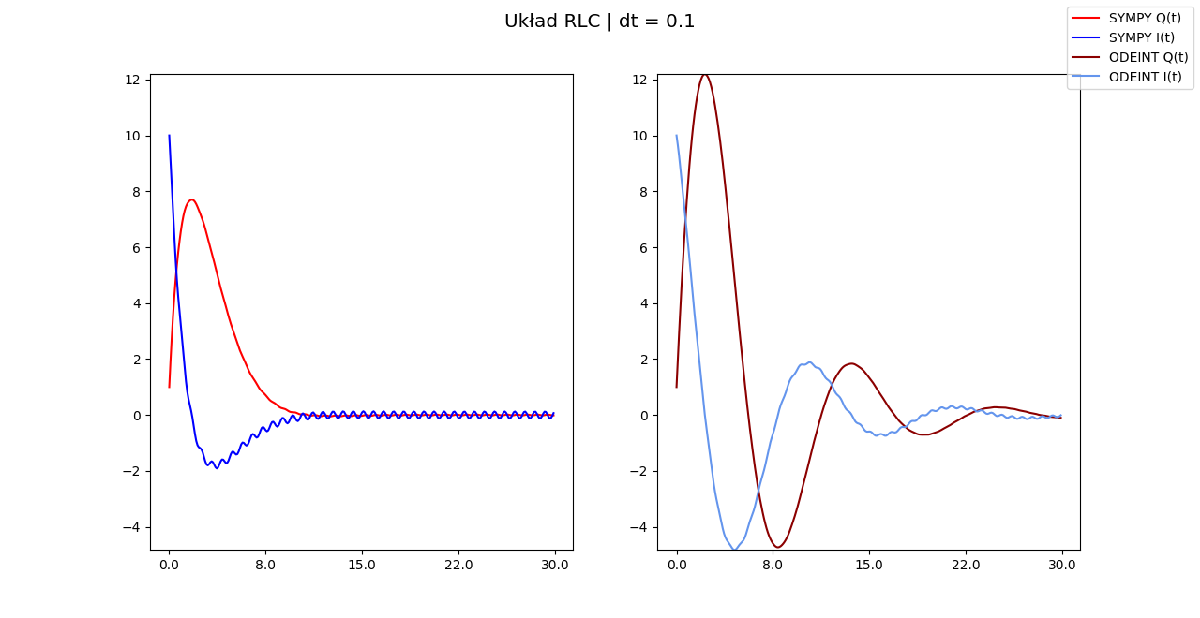

`Figure 12: Wykresy I(t), Q(t) układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 8`

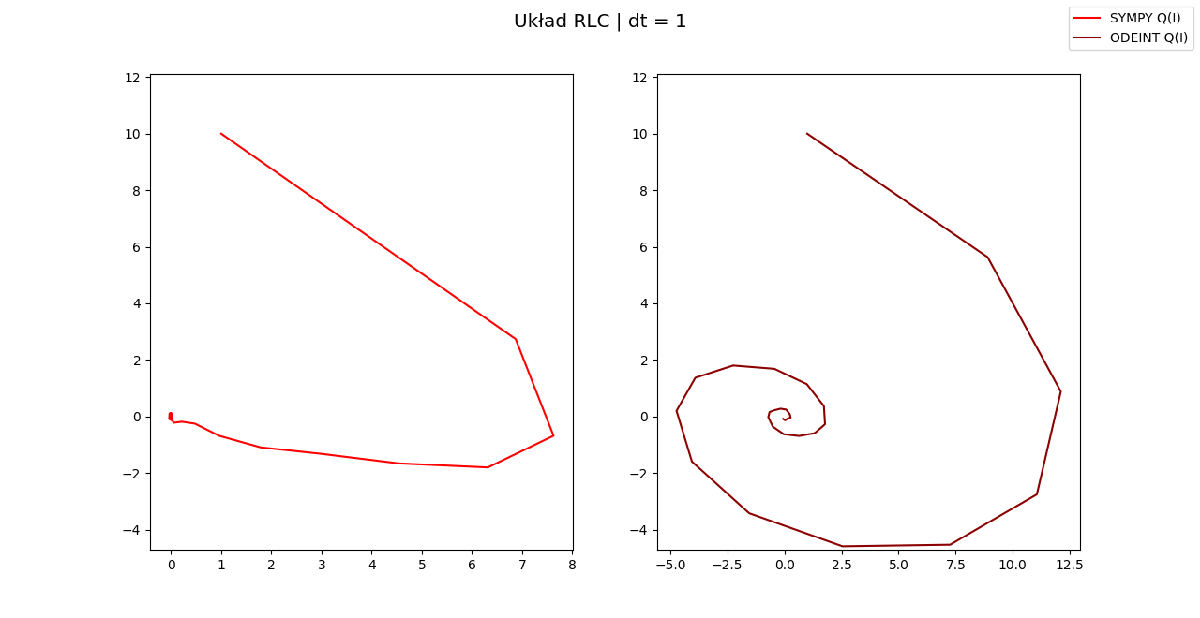

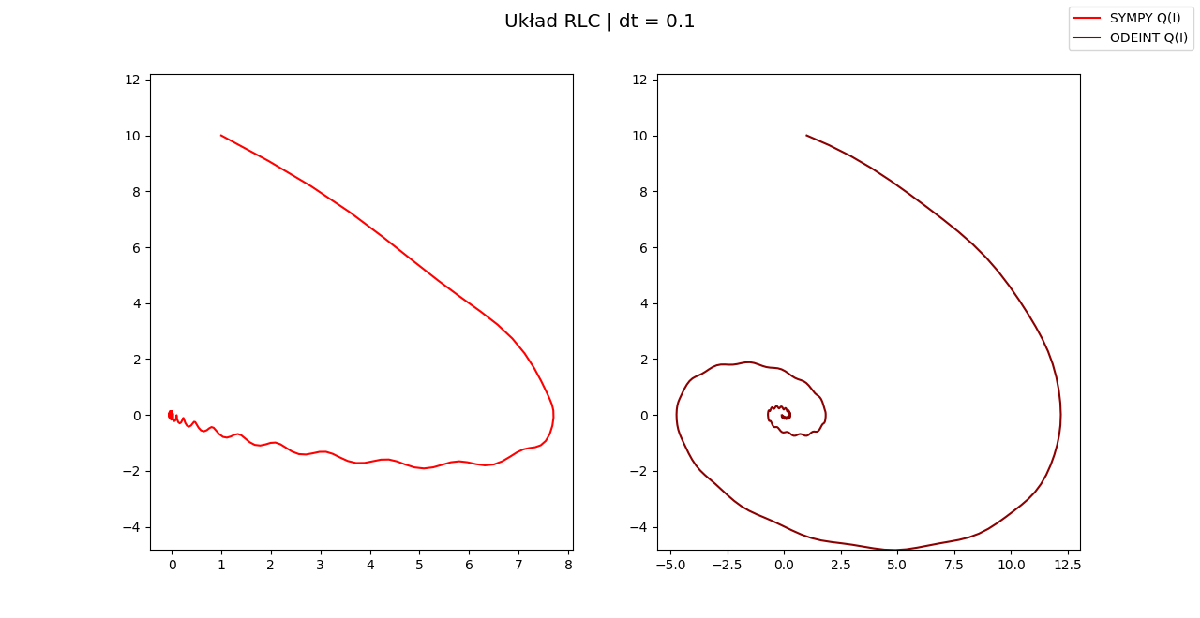

`Figure 13: Wykresy Q(I) układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 8`

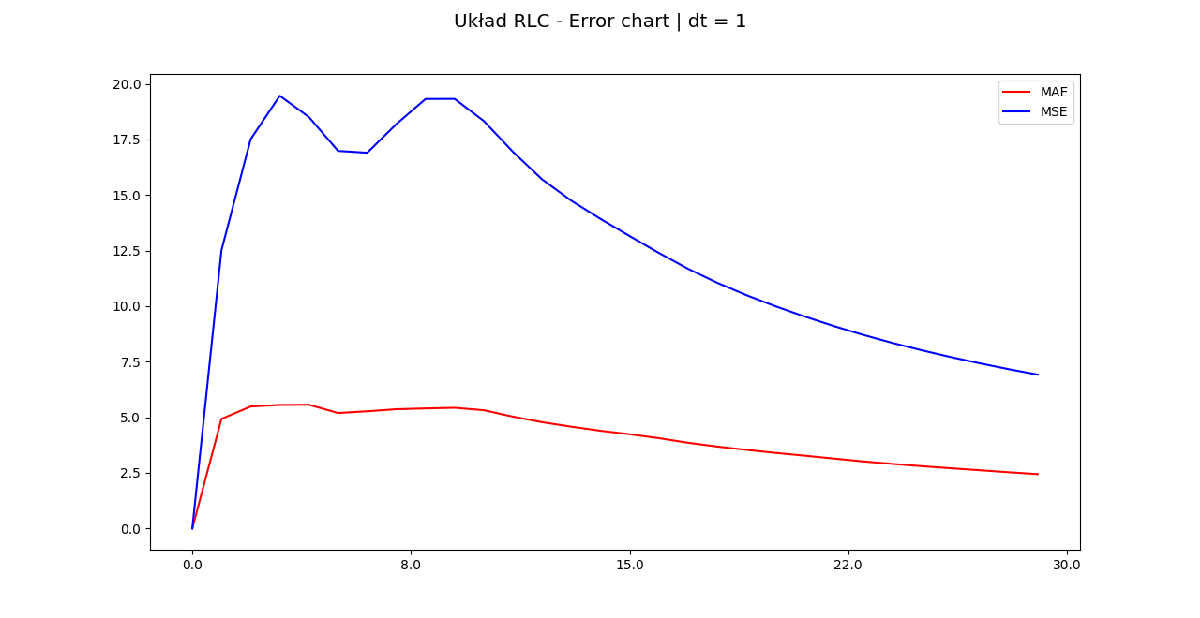

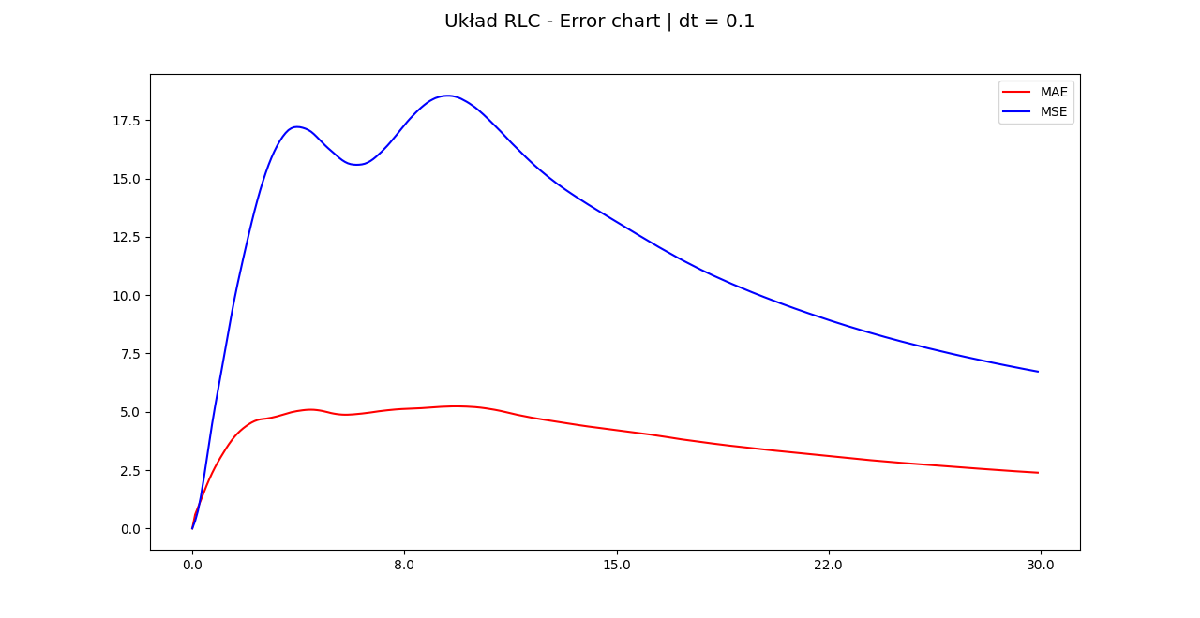

`Figure 14: Wykresy średniego błędu kwadratowego i średniego błędu bezwzględnego układu RLC przy parametrach q0 = 1, i0 = 10, R = 1, L = 3, C = 1, A = 1, Omega = 8`

`ŚREDNI BŁĄD APROKSYMACJI`

- `dt = 1`

MSE:  6.6868,  MAE:  2.3618

- `dt = 0.1`

MSE:  6.7096,  MAE:  2.3825

#### `WNIOSKI`

`Obie metody wyliczania układów są algorytmami rozwiązywania równań różniczkowych, zatem spodziewać możemy się, że w zależności od doboru dyskretnego kroku czasowego, otrzymany wynik będzie jedynie przybliżeniem rozwiązania. Metoda odeint wykorzystuje algorytm lsoda, który dynamicznie dostosowywuje sposób podejścia do rozwiązania ODE (wybierając pomiędzy różnymi metodami rozwiązywania ODE takimi jak metoda Runge-Kutta), z tego powodu obserwujemy, że szybciej zbiega on do rzeczywistego rozwiązania niż metoda Eulera. Jest on również z tego powodu stosunkowo mniej wrażliwy na niewiekie zmiany dt dla większości układów niż algorytm Eulera. Wciąż jednak, wybór kroku czasowego dt jest znaczący, ponieważ nie dokonujemy dyskretyzacji modelu, a rekurencyjnego podejścia rozwiązania numerycznego, co sprawia, że błędy wynikające z doboru dt nakładają się wraz z każdą iteracją, co uwidacznia się dla średnich kwadratowych błędów aproksymacji.`